Chiamata della funzione ImportData per estrarre i dati dalla cartella Data così da accedervi in modo automatico. Si è poi ipotizzato che la cartella contenga un numero uguale di dati di pazienti sani e pazienti che soffrono di Alzheimer.

Data=my_importdata();
n_Data_elements=numel(Data);
n_AD_elments=n_Data_elements/2; % numero di pazienti malati 
n_C_elements=n_Data_elements/2; % numero di pazienti sani


Pre-allocazione delle matrici in cui verrano inseriti gli spettri dei singoli soggetti.

[pxx_test, f_test]= my_pwelch(Data{1,1},1000,500,1024,60);  
% si calcola lo spettro e vettore delle frequenze del primo soggetto così da otterene le dimensioni delle matrici
                                                            
n_pxx=numel(pxx_test);

%preallochiamo due matrici che conterranno rispettivamente 
% tutti gli spettri dei pazienti sani e malati 
pxx_matrix_AD = zeros(n_pxx,n_AD_elments);
pxx_matrix_C = zeros(n_pxx,n_C_elements);

%stessa cosa di sopra, ci servirà per confontare la nostra funzione per il
%calcolo della PXX con quella di matlab
pxx_matrix_AD_Matlab = zeros(n_pxx,n_AD_elments);
pxx_matrix_C_Matlab = zeros(n_pxx,n_C_elements);

Riempimento delle matrici chiamado la funzione my_pwelch

for ad_index=1:n_AD_elments
     
     [pxx_matrix_AD(:,ad_index),f] = my_pwelch(Data{ad_index,1},1000,500,1024,60);
     [pxx_matrix_AD_Matlab(:,ad_index),f_M] = my_pwelch_matlab(Data{ad_index,1});

end
 
for c_index=1:n_C_elements
   
     [pxx_matrix_C(:,c_index),f] =  my_pwelch(Data{c_index+n_AD_elments,1},1000,500,1024,60);
     [pxx_matrix_C_Matlab(:,c_index),f_M] =  my_pwelch_matlab(Data{c_index+n_AD_elments,1});

end

Calcolo degli spettri medi. (Per utilizzare correttamente la funzione mean è stato necessario trasporre le matrici degli spettri)

pxx_matrix_AD = (pxx_matrix_AD)'; 
pxx_matrix_mean_AD = mean(pxx_matrix_AD);
 
pxx_matrix_C = (pxx_matrix_C)';
pxx_matrix_mean_C = mean(pxx_matrix_C);
 
pxx_matrix_AD_Matlab=(pxx_matrix_AD_Matlab)';
pxx_matrix_mean_AD_Matlab=mean(pxx_matrix_AD_Matlab);
 
pxx_matrix_C_Matlab=(pxx_matrix_C_Matlab)';
pxx_matrix_mean_C_Matlab=mean(pxx_matrix_C_Matlab);

In questo passaggio si è calcolato il valore delle deviazioni standard rispettive a ogni frequenza e in seguito delle curve medie +/- la deviazione standard

%pre-allochiamo le matrici che conterranno i valori delle deviazioni
%standard
std_matrix_AD = zeros(1,n_pxx);
std_matrix_C = zeros(1, n_pxx);
 
for matrix_column= 1:n_pxx
     
     std_matrix_AD(1, matrix_column) = std(pxx_matrix_AD(:,matrix_column));
     std_matrix_C(1, matrix_column) = std(pxx_matrix_C(:,matrix_column));
end
 
pxx_matrix_UP_AD = pxx_matrix_mean_AD + std_matrix_AD;
pxx_matrix_DOWN_AD = abs(pxx_matrix_mean_AD - std_matrix_AD); % E' stato necessario usare il modulo poichè 
                                                              % i valori negarivi di non sono 
                                                              % esprimibili con la scala log
pxx_matrix_UP_C = pxx_matrix_mean_C + std_matrix_C;
pxx_matrix_DOWN_C = abs(pxx_matrix_mean_C - std_matrix_C);    %stessa cosa qui

Per verificare la correttezza della funzione my_pwelch si è deciso di porre nello stesso grafico gli spettri di potenza medi ottenuti con la funzione di Matlab specifica (pwelch) con quelli ottenuti attraverso my_pwelch. Si può notare che l'andamento delle curve corrispondenti presenta delle delle leggere variazioni che sono del tutto normali.

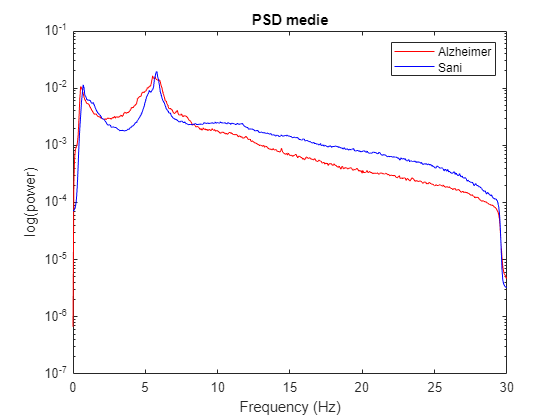

figure(1)
semilogy(f,pxx_matrix_mean_AD,'r',f,pxx_matrix_mean_C,'b');
xlabel('Frequency (Hz)');
ylabel('log(power)');
title('PSD medie');
legend( 'Alzheimer', 'Sani');

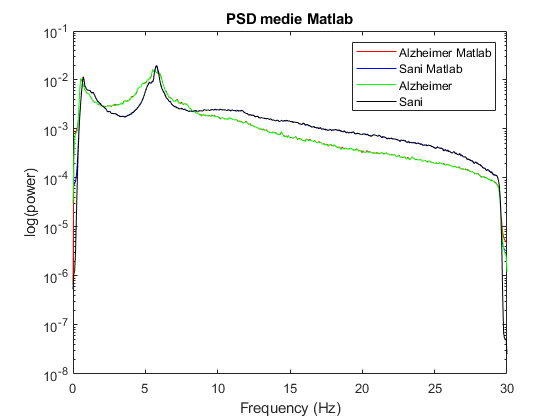



figure(2)
semilogy(f,pxx_matrix_mean_AD,'r',f,pxx_matrix_mean_C,'b');
hold on
semilogy(f,pxx_matrix_mean_AD_Matlab,'g',f,pxx_matrix_mean_C_Matlab,'k');
hold off
title('PSD medie Matlab');
legend('Alzheimer Matlab','Sani Matlab',  'Alzheimer', 'Sani');
ylabel('log(power)');
xlabel('Frequency (Hz)');

Il grafico che segue mostra gli spettri di potenza media con i rispettivi intervalli di confidenza così da poterne vedere il comportamento e le aree di intersezione. Per graficare le aree colorate è stata utilizzata la funzione FillBetween ( Autore: Benjamin T. Vincent ).

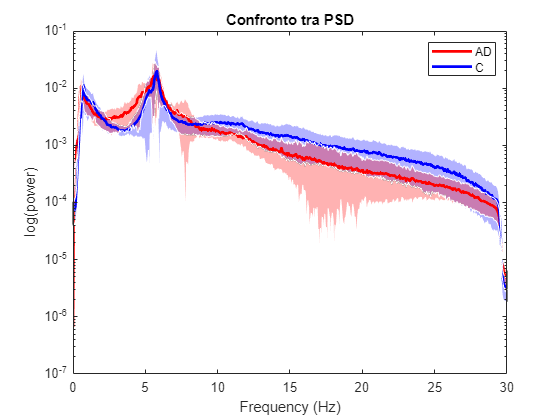

figure (3)
h = semilogy(f,pxx_matrix_mean_AD,'r', f,pxx_matrix_mean_C,'b');
set (h(1), 'linewidth', 2);
set (h(2), 'linewidth', 2);
title('Confronto tra PSD');
xlabel('Frequency (Hz)');
ylabel('log(power)');

opts={'FaceColor', 'r','FaceAlpha', 0.3};
[y1handle_AD, y2handle_AD, ~] = fill_between(f, pxx_matrix_UP_AD, pxx_matrix_DOWN_AD, [], opts{:});

opts={'FaceColor', 'b', 'FaceAlpha', 0.3}; 
[y1handle_C, y2handle_C, h_C] = fill_between(f, pxx_matrix_UP_C, pxx_matrix_DOWN_C, [], opts{:});

legend([h(1) h(2)],{'AD','C'});

Calcolo delle potenze assolute e relative

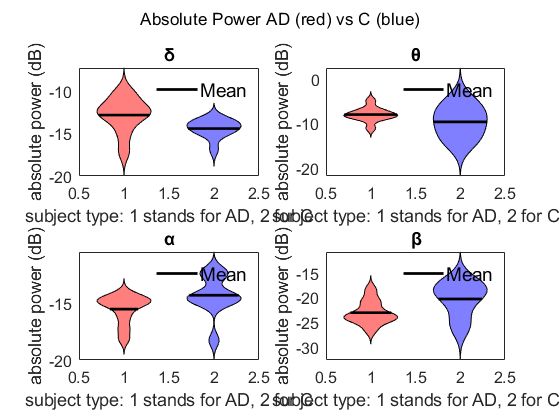

% Si calcolano le potenze del primo soggetto per verificarne del dimensioni e
% poter quindi pre-allocare delle matrici opportune
[abs_prova, rel_prova]=compute_abs_rel_power(pxx_matrix_AD(1,:), f);
 
n_abs_elements=size(abs_prova,2);
n_rel_elements=size(rel_prova,2);
 
% si pre-allocano 4 matrici:esse conterranno in ogni riga i valori di
% potenza (rispettivamente relativa e assoluta) per tutte le bande del
% singolo soggetto. Così ogni colonna conterrà tutti i valori per una
% deterinata banda di tutti i soggetti
 
abs_matrix_AD=zeros(n_AD_elments,n_abs_elements);
rel_matrix_AD=zeros(n_AD_elments,n_rel_elements);

abs_matrix_C=zeros(n_AD_elments,n_abs_elements);
rel_matrix_C=zeros(n_AD_elments,n_rel_elements); 

% riempimento delle matrici
 
for ad_index=1:n_AD_elments
     
   [ abs_matrix_AD(ad_index,:), rel_matrix_AD(ad_index,:)]=compute_abs_rel_power(pxx_matrix_AD(ad_index,:), f);
   [ abs_matrix_C(ad_index,:), rel_matrix_C(ad_index,:)]=compute_abs_rel_power(pxx_matrix_C(ad_index,:), f);

end

% per ciascuna banda vengono plottati insieme i grafici 
% dei soggetti sani e malati per confrontarli 
abs_matrix_AD = db(abs_matrix_AD,'power'); % conversione in dB
abs_matrix_C = db(abs_matrix_C,'power');   % conversione in dB
% Nota: solo i valori di potenza assoluta sono stati espressi in decibel

figure(4)

subplot(2,2,1)
plot1=[abs_matrix_AD(:,1),abs_matrix_C(:,1)];
[~, ~, ~, ~, ~] = violin(plot1,'facecolor',[1 0 0  ;0 0 1]);
title('δ');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('absolute power (dB)')

subplot(2,2,2)
plot2=[abs_matrix_AD(:,2),abs_matrix_C(:,2)];
[~, ~, ~, ~, ~] = violin(plot2,'facecolor',[1 0 0  ;0 0 1]);
title('θ');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('absolute power (dB)')


subplot(2,2,3)
plot3=[abs_matrix_AD(:,3),abs_matrix_C(:,3)];
[~, ~, ~, ~, ~] = violin(plot3,'facecolor',[1 0 0  ;0 0 1]);
title('α');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('absolute power (dB)')

subplot(2,2,4)
plot4=[abs_matrix_AD(:,4),abs_matrix_C(:,4)];
[~, ~, ~, ~, ~] = violin(plot4,'facecolor',[1 0 0  ;0 0 1]);
title('β');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('absolute power (dB)')

sgtitle('Absolute Power AD (red) vs C (blue)');

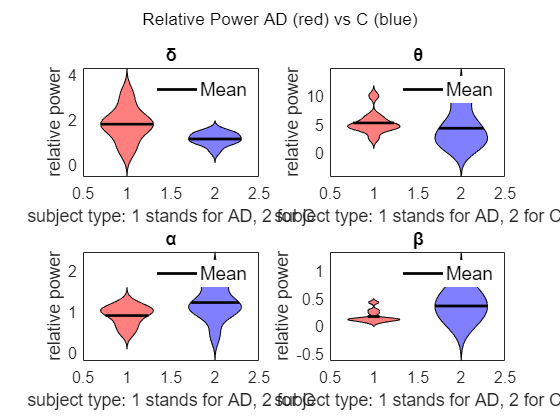


figure(5)

subplot(2,2,1)
plot5=[rel_matrix_AD(:,1),rel_matrix_C(:,1)];
[~, ~, ~, ~, ~] = violin(plot5,'facecolor',[1 0 0  ;0 0 1]);
title('δ');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('relative power')

subplot(2,2,2)
plot6=[rel_matrix_AD(:,2),rel_matrix_C(:,2)];
[~, ~, ~, ~, ~] = violin(plot6,'facecolor',[1 0 0  ;0 0 1]);
title('θ');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('relative power')

subplot(2,2,3)
plot7=[rel_matrix_AD(:,3),rel_matrix_C(:,3)];
[~, ~, ~, ~, ~] = violin(plot7,'facecolor',[1 0 0  ;0 0 1]);
title('α');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('relative power')

subplot(2,2,4)
plot8=[rel_matrix_AD(:,4),rel_matrix_C(:,4)];
[~, ~, ~, ~, ~] = violin(plot8,'facecolor',[1 0 0  ;0 0 1]);
title('β');
xlabel('subject type: 1 stands for AD, 2 for C');
ylabel('relative power')

sgtitle('Relative Power AD (red) vs C (blue)');

Implementazione del t-tet di Matlab

% pre-allochiamo le matrici per i t-test: svolgeremo dei test tra le stesse
% bande dei pazienti malati e sani e tra le potene medie dei pazienti sani
% e malati
Hypothesis_and_P_Value_ABS_Pow = zeros(n_abs_elements, 2);   % qui andremo a salvare i risultati dei test sulle potenze assolute
Hypothesis_and_P_Value_REL_Pow = zeros(n_rel_elements, 2);   % qui andremo a salvare i risultati dei test sulle potenze relative

%Hypothesis_and_P_Value_PXX_Mean = zeros(1, 2); % qui andremo a salvare i risultati dei test sulle pxx medie
%[Hypothesis_and_P_Value_PXX_Mean(1,1),Hypothesis_and_P_Value_PXX_Mean(1,2)] = ttest2(pxx_matrix_mean_AD,pxx_matrix_mean_C); %eseguiamo il test sulle pxx medie

for test_index=1:size(Hypothesis_and_P_Value_ABS_Pow,1)
    
    % svolgiamo i test per ogni banda
    [h_abs, p_abs] = ttest2(abs_matrix_AD(:,test_index),abs_matrix_C(:,test_index)); 
    [h_rel, p_rel] = ttest2(rel_matrix_AD(:,test_index),rel_matrix_C(:,test_index)); 

    % h rappresenta l'esito del test (1=ipotesi riufiutata, 0=ipotesi accettata), mentre p è il P-value del rispettivo t-test
   
    % salviamo i risultati nelle rispettive matrici: nella prima colonna
    % avremo gli esiti, nella seconda i p-value
    Hypothesis_and_P_Value_ABS_Pow(test_index, :) = [h_abs, p_abs];
    Hypothesis_and_P_Value_REL_Pow(test_index, :) = [h_rel, p_rel];
end

%eseguiamo ora i t-test per le varie bande delle PSD

[Pxx_delta_AD,Pxx_theta_AD,Pxx_alpha_AD,Pxx_beta_AD]=compute_Pxx_bands(pxx_matrix_mean_AD,f);
[Pxx_delta_C,Pxx_theta_C,Pxx_alpha_C,Pxx_beta_C]=compute_Pxx_bands(pxx_matrix_mean_C,f);

[h_delta, P_Value_Pxx_delta]=ttest2(Pxx_delta_AD,Pxx_delta_C);
[h_theta, P_Value_Pxx_theta]=ttest2(Pxx_theta_AD,Pxx_theta_C);
[h_alpha, P_Value_Pxx_alpha]=ttest2(Pxx_alpha_AD,Pxx_alpha_C);
[h_beta, P_Value_Pxx_beta]=ttest2(Pxx_beta_AD,Pxx_beta_C);

Test_Matrix = [Hypothesis_and_P_Value_ABS_Pow ;Hypothesis_and_P_Value_REL_Pow; h_delta, P_Value_Pxx_delta;...
             h_theta, P_Value_Pxx_theta; h_alpha, P_Value_Pxx_alpha; h_beta, P_Value_Pxx_beta];
         
% mostriamo la tabella che riassume tutti i risultati dei t -test 
% da notare come i P-Value prossimi a 0 vengano approssimati a 0      
                  
T = array2table(Test_Matrix,'VariableNames',{'Hypothesis','P Value'},...
    'RowNames',{'δ ABS';'θ ABS';'α ABS';'β ABS'; 'δ REL';'θ REL';'α REL';'β REL';'δ PSD'; 'θ PSD'; 'α PSD'; 'β PSD'})

T = 12×2 table
             Hypothesis     P Value  
             __________    __________

    δ ABS        1           0.043102
    θ ABS        0            0.19259
    α ABS        0           0.092693
    β ABS        0           0.050878
    δ REL        1           0.018579
    θ REL        0            0.43397
    α REL        0           0.052163
    β REL        1           0.027166
    δ PSD        1         1.6662e-20
    θ PSD        0            0.16667
    α PSD        1         5.9242e-26
    β PSD        1         2.5939e-32


# **FUNZIONI:**

Funzione My_ImportData

function [Data] = my_importdata()
a = dir('data');       % funzione di matlab per leggere il contenuto di una cartella
Data=cell(length(a)-2,1); %scegliamo di inerire i dati in un cell array per facilitarne l'accesso. Pre-allochiamo qui il suddetto cell array 
for data_index = 3:length(a)    % ignoriamo i primi 2 elementi,non sono informazioni utili                  
       filename = a(data_index).name;                % a ogni ciclo viene salvato in 'filename' il singolo file.mat          
       l = load(strcat('data/', filename)); % otteniamo il percorso di ogni singolo file concatenando con
                                            % la funzione strcat e carichiamo ciascuno di essi con
                                            % load; a ogni ciclo for carichiamo il file nella struttura
                                            % cell Data
       Data(data_index-2) = struct2cell(l);  
end

end %of the function

Funzione per il calcolo della PSD usando la funzione pwelch() di Matlab

function [pxx, f] = my_pwelch_matlab(data) % funzione per calcolare spettro e le frequenze su cui lavora

%i valori numerici che utilizziamo (nfft,wdw, overlap,fs) sono stati scelti
%in base a quanto visto sulle esercitazioni di grader. Il valore di fs in
%particolare è scelto per avere le frequenze nella banda 0-30 Hz

n_channels=size(data,1);
nfft=1024; 

 %pre-allochiamo la matrice nella quale salveremo in ogni riga la pxx di
 %ogni canale del dato in ingresso
 
 y_pxx=zeros(n_channels,nfft/2+1) ;
 
 for channel_index=1:n_channels
     
     [y_pxx(channel_index,:),f]=pwelch(data(channel_index,:), hamming(1000), 500, nfft, 60);
     
 end
 % eseguiamo la sommatoria delle pxx
 pxx=sum(y_pxx);
 
 Q=trapz(pxx);         % calcolo dell' area sottesa sotto al segnale
 pxx = pxx/Q;         % dividiamo lo spettro per tale valore di area
 
 % trasponiamo f per far si che coincida con il vettore che otteniamo
 % implementando la nostra funzione per il calcolo della pxx
 f=f';
 end  %of the function

Funzione my_pwelch per il calcolo della PSD utilizzando il metodo del periodogramma

function [PXX, f] = my_pwelch(sig,wdw,overlap,nfft,fs) %funzione che abbiamo implementato noi per il calcolo della pxx
    
n_channels=size(sig,1);% numero di canali
n_elements=size(sig,2);% numero di elementi per ogni canale
window_diff=(wdw-overlap);% è la dimensione effettiva che occupa ogni singola finestra, essendoci overlap
n_wdw=round(n_elements/window_diff);% il numero di finestre che andremo ad utilizzare

xStart = (1:window_diff:(n_elements-2*window_diff));% vettore degli indici di inizio finestre
xEnd   = (wdw:window_diff:n_elements);% vettore degli indici di fine finestre
    
% pre-allochiamo la matrice finale : è una matrice 3D e ogni pagina
% rappresenta un canale; per ogni pagina, andremo a inserire in ogni
% riga una singola finestra corrispondente a determinati campioni del
% dato canale

y_overlap = zeros(numel(xStart),nfft,n_channels);
    
    
for  idx_channels=1:n_channels
       for idx_windows = 1:length(xStart) 
             y_overlap(idx_windows,:,idx_channels) = abs(fft(sig(idx_channels,xStart(idx_windows):xEnd(idx_windows)),nfft)).^2; %calcolo del modulo quadro della fft dei valori del segnale in ingresso corrispondenti alla singola finestra

       end 
end 
    
y_overlap2 = zeros(numel(xStart),(nfft/2+1),idx_channels);%essendo la fft simmetrica, ci servirà solo la prima metà dei campioni(i successivi sono identici e specchiati rispetto ai primi (nfft/2+1))
  
for idx_windows = 1:length(xStart),idx_channels=1:n_channels;
          
       y_overlap2(idx_windows,:,idx_channels)=y_overlap(idx_windows,1:(nfft/2+1),idx_channels);
end
      
% pre-allochiamo la matrice nella quale metteremo le medie dei segnali
% contenuti in ciascun canale

sig_Mean=zeros(n_channels,size(y_overlap2,2));
      
for idx_channles=1:n_channels
       sig_Mean(idx_channles,:)=(mean(y_overlap2(:,:,idx_channles))); % calcoliamo le medie dei singoli canali
end
      
PXX_coeff=2/(n_wdw*wdw);
% calcolo del coefficiente della formula per calcolare lo spettro
PXX=PXX_coeff*(sum(sig_Mean));%valore effettivo della PXX, ottenuto sommando tutte le medie

Q = trapz(PXX);  % calcolo l' area sottesa sotto al segnale
PXX = PXX/Q;  % normalizziamo la PXX
f=linspace(0, fs/2 , size(y_overlap2,2)); % creiamo il vettore delle frequenze per f : tali valori servono per renderlo uguale a quello creato da matlab così da poter confrontare i grafici.

end %of the function

Funzione per il calcolo delle potenze relative e assolute 

function [abs_powers,rel_powers] = compute_abs_rel_power(data,f)

% in ingresso mettiamo solamente il vettore del quale calcoleremo le potenze e il vettore 
% delle frequenze totale in uscita avremo quindi due vettori, il primo che conterrà
% le potenze assolute di ogni banda, mentre il secondo conterrà le
% potenze relative di ogni banda.


%individuiamo gli indici delle varie fasce di frequenza all'interno del
%vettore delle frequenze totali

f_delta=find(f>=2 & f<=4);
f_theta=find(f>=5 & f<=7);
f_alpha=find(f>=8 & f<=13);
f_beta=find(f>=14 & f<=30);
f_abs=find(f>=1 & f<=30);
 
%preallochiamo due vettori di 4 colonne, essendo 4 le bande di frequenza
%che considereremo.Così in ogni posizione del vettore avremo il valore di
%potenza di una determinata banda

n_power_bands=4;
abs_powers=zeros(1,n_power_bands);
rel_powers=zeros(1,n_power_bands);

 %ci servono i valori del dato in ingresso corrispondenti agli indici della
 %determinata banda: preallochiamo allora 5 vettori, uno per ogni banda più
 %uno per la banda totale 1-30 Hz, ciascuno dei quali conterrà i valori
 %del dato in ingresso in quella specifica banda
 
abs_power_d=zeros(1,numel(f_delta)); %valori nella banda delta
abs_power_th=zeros(1,numel(f_theta)); %valori nella banda theta
abs_power_a=zeros(1,numel(f_alpha)); %valori nella banda alpha
abs_power_b=zeros(1,numel(f_beta)); %valori della banda beta
abs_power_abs=zeros(1,numel(f_abs)); %valori nella banda totale 1-30 Hz

%riempiamo le varie matrici coi valori del dato in ingresso
%corrispondenti alle specifiche bande, valori compresi tra gli indici
%selezionati

abs_power_d(1,:)=data(1,f_delta);

abs_power_th(1,:)=data(1,f_theta);

abs_power_a(1,:)=data(1,f_alpha);

abs_power_b(1,:)=data(1,f_beta);

abs_power_abs(1,:)=data(1,f_abs);

%per ogni banda, calcoliamo il valore minimo e massimo, così da avere la
%lunghezza della banda.Essa ci servirà per calcolare la potenza assoluta.

delta_band=abs(max(f(f>=2 & f<=4))-min(f(f>=2 & f<=4)));
theta_band=abs(max(f(f>=5 & f<=7))-min(f(f>=5 & f<=7)));
alpha_band=abs(max(f(f>=8 & f<=13))-min(f(f>=8 & f<=13)));
beta_band=abs(max(f(f>=14 & f<=30))-min(f(f>=14 & f<=30)));
abs_band=abs(max(f(f>=1 & f<=30))-min(f(f>=1 & f<=30)));

%calcoliamo la potenza assoluta per l'intero spettro, che ci servirà per
%calcolare le potenze relative delle altre bande

abs_power_abs=(sum(abs_power_abs))/abs_band;

%calcoliamo le potenze assolute e relative di ogni banda

abs_power_d=(sum(abs_power_d))/delta_band;
rel_power_d=abs_power_d/abs_power_abs;

abs_power_th=(sum(abs_power_th))/theta_band;
rel_power_th=abs_power_th/abs_power_abs;

abs_power_a=(sum(abs_power_a))/alpha_band;
rel_power_a=abs_power_a/abs_power_abs;

abs_power_b=(sum(abs_power_b))/beta_band;
rel_power_b=abs_power_b/abs_power_abs;

%riempiamo le matrici finali coi valori trovati
abs_powers(1,:)=[abs_power_d,abs_power_th,abs_power_a,abs_power_b];
rel_powers(1,:)=[rel_power_d,rel_power_th,rel_power_a,rel_power_b];  

end %of the function

function [pxx_band_d,pxx_band_th,pxx_band_a,pxx_band_b] = compute_Pxx_bands(data,f)

%Questa funzione serve per suddividere le PSD nelle 4 bande di frequenza per
%poter poi andare a eseguire i t-test sulle singole bande.
%In uscita dalla funzione avremo quindi la PSD suddivisa nelle 4 bande.
%Il funzionamento della funzione è del tutto analogo a quello della
%funzione per il calcolo delle potenze relative e assolute.

f_delta=find(f>=2 & f<=4);
f_theta=find(f>=5 & f<=7);
f_alpha=find(f>=8 & f<=13);
f_beta=find(f>=14 & f<=30);
 
pxx_band_d=zeros(1,numel(f_delta)); 
pxx_band_th=zeros(1,numel(f_theta)); 
pxx_band_a=zeros(1,numel(f_alpha)); 
pxx_band_b=zeros(1,numel(f_beta)); 

pxx_band_d(1,:)=data(1,f_delta);
pxx_band_th(1,:)=data(1,f_theta);
pxx_band_a(1,:)=data(1,f_alpha);
pxx_band_b(1,:)=data(1,f_beta);

end %of the function